# mask analysis

## correlated analysis

% params
mask_sz = size(mask)

mask_sz =         1024        1024          10


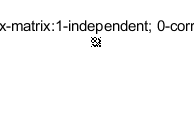

corr_v  =corrcoef(reshape(mask,[mask_sz(1)*mask_sz(2),mask_sz(3)]));
[corr_idx_matrix, corr_groups] = corr_group(corr_v, 0.8);

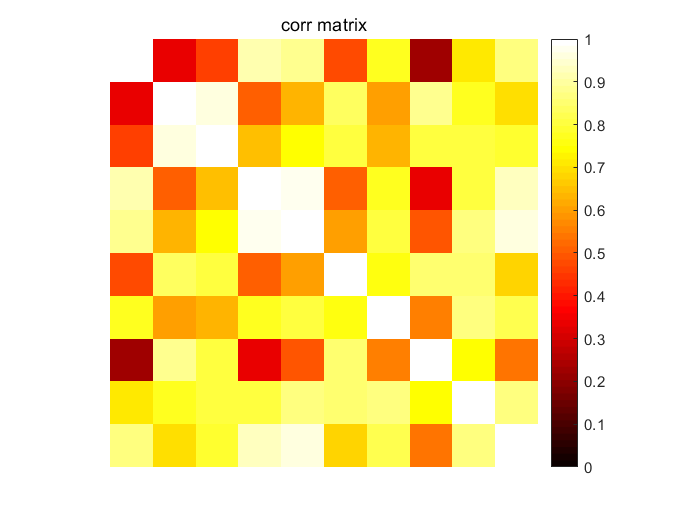


figure
imshow(corr_v, 'InitialMagnification','fit')
colormap('hot')
colorbar()
title('corr matrix')

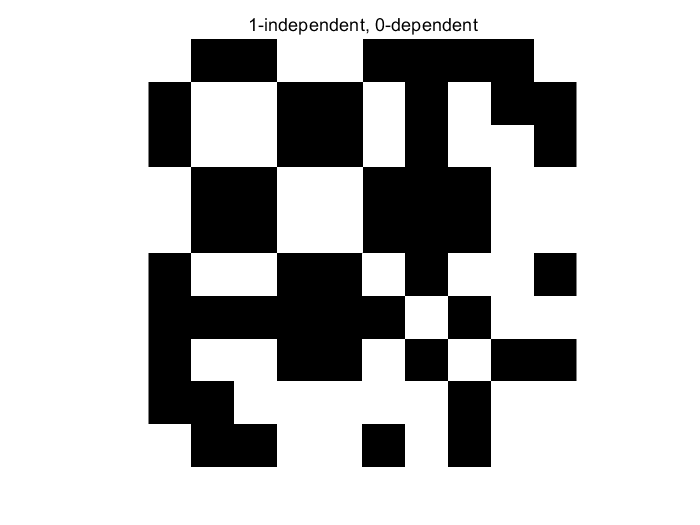


figure
imshow(1-corr_idx_matrix, 'InitialMagnification','fit')
title('0-independent, 1-dependent')